# Lshape Problem

Lshpae solves the Poisson equation $-\Delta u =f$ in $\Omega$ and $u = g_D$ on $\partial \Omega$ in a Lshaped domain $\Omega=(-1,1)^2 \setminus \{[0,1)\times (-1,0]\}$ using adaptive finite element method (AFEM). We choose f and g_D such that the exact solution is  $u = r^{\beta}\sin(\beta\theta), \beta = 2/3$ in the polar coordinate. Then $u\in H^s(\Omega)$ for $s<5/3$ and thus finite element methods based on quasi-uniform grids will not convergence in optimal order.

Detailed explanation can be found in  [AFEM doc](https://www.math.uci.edu/~chenlong/ifemdoc/afem/afemdoc.html)

See also crack, Kellogg

Copyright (C) Long Chen. See COPYRIGHT.txt for details.

close all;

## Parameters

maxN = 1e4;     theta = 0.4;    maxIt = 100; 
N = zeros(maxIt,1);   
errL2 = zeros(maxIt,1);   
errH1 = zeros(maxIt,1); 
erreta = zeros(maxIt,1);

## Generate an initial mesh and set up PDE data

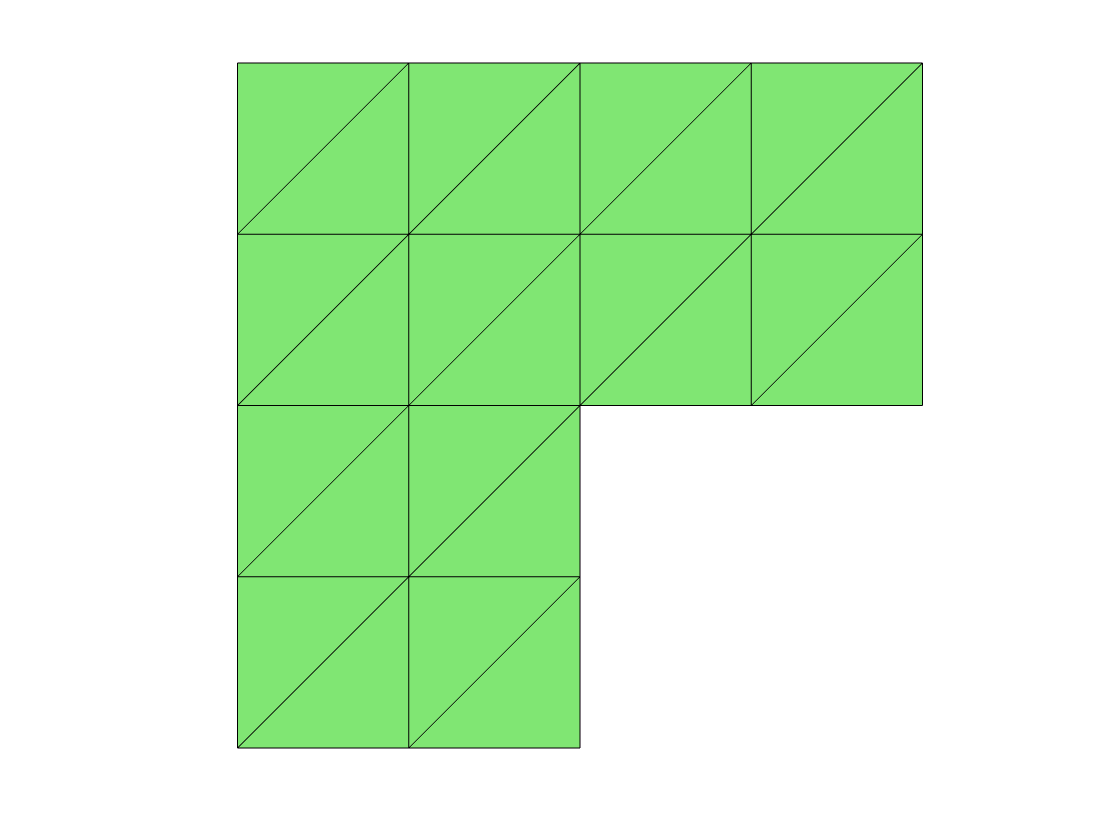

[node,elem] = squaremesh([-1,1,-1,1],0.5);
[node,elem] = delmesh(node,elem,'x>0 & y<0');
showmesh(node,elem);

bdFlag = setboundary(node,elem,'Dirichlet');
pde = Lshapedata;

## Adaptive Finite Element Method

**SOLVE** -> **ESTIMATE** -> **MARK** -> **REFINE**

Multigrid V-cycle Preconditioner with Conjugate Gradient Method
#dof:     2231,  #nnz:    10757, smoothing: (1,1), iter:  7,   err = 4.05e-10,   time = 0.36 s


Multigrid V-cycle Preconditioner with Conjugate Gradient Method
#dof:     2860,  #nnz:    13804, smoothing: (1,1), iter:  7,   err = 3.24e-10,   time = 0.22 s


Multigrid V-cycle Preconditioner with Conjugate Gradient Method
#dof:     3631,  #nnz:    17541, smoothing: (1,1), iter:  7,   err = 4.38e-10,   time = 0.15 s


Multigrid V-cycle Preconditioner with Conjugate Gradient Method
#dof:     4585,  #nnz:    22285, smoothing: (1,1), iter:  7,   err = 4.78e-10,   time = 0.21 s


Multigrid V-cycle Preconditioner with Conjugate Gradient Method
#dof:     5785,  #nnz:    28297, smoothing: (1,1), iter:  7,   err = 4.25e-10,   time = 0.14 s


Multigrid V-cycle Preconditioner with Conjugate Gradient Method
#dof:     7278,  #nnz:    35678, smoothing: (1,1), iter:  7,   err = 4.25e-10,   time = 0.24 s


Multigrid V-cycle Preconditioner with Conjugate Gradient Method
#dof:     9197,  #nnz:    45119, smoothing: (1,1), iter:  7,   err = 3.97e-10,   time = 0.25 s


Multigrid V-cycle Preconditioner with Conjugate Gradient Method
#dof:    11593,  #nnz:    56969, smoothing: (1,1), iter:  7,   err = 3.24e-10,   time = 0.47 s


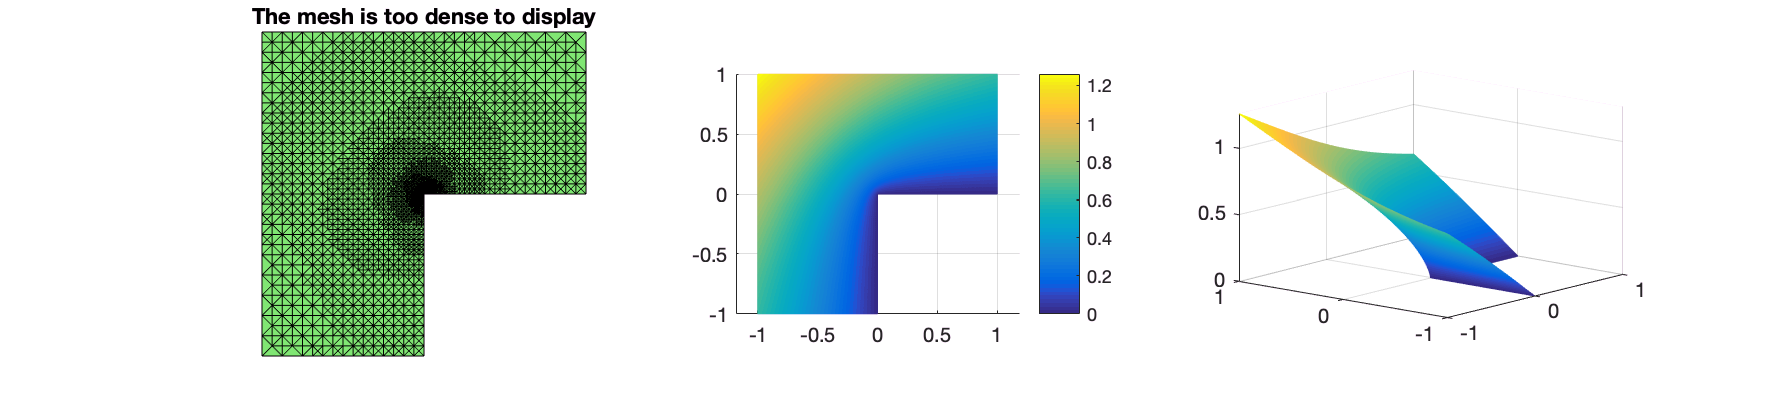

for k = 1:maxIt
    % Step 1: SOLVE
    [soln,eqn,info] = Poisson(node,elem,bdFlag,pde);
    figure(1);  showresult(node,elem,soln.u,[-50,12]);    
    % Step 2: ESTIMATE
%     eta = estimaterecovery(node,elem,u);         % recovery type
    eta = estimateresidual(node,elem,soln.u,pde);    % residual type
    % Record error and number of vertices
    N(k) = size(node,1);
    errH1(k) = getH1error(node,elem,pde.Du,soln.Du);
    errL2(k) = getL2error(node,elem,pde.exactu,soln.u);
    erreta(k) = sqrt(sum(eta.^2));
    if (N(k)>maxN), break; end        
    % Step 3: MARK
    markedElem = mark(elem,eta,theta);
    % Step 4: REFINE
    [node,elem,bdFlag] = bisect(node,elem,markedElem,bdFlag);
end

## Plot convergence rates

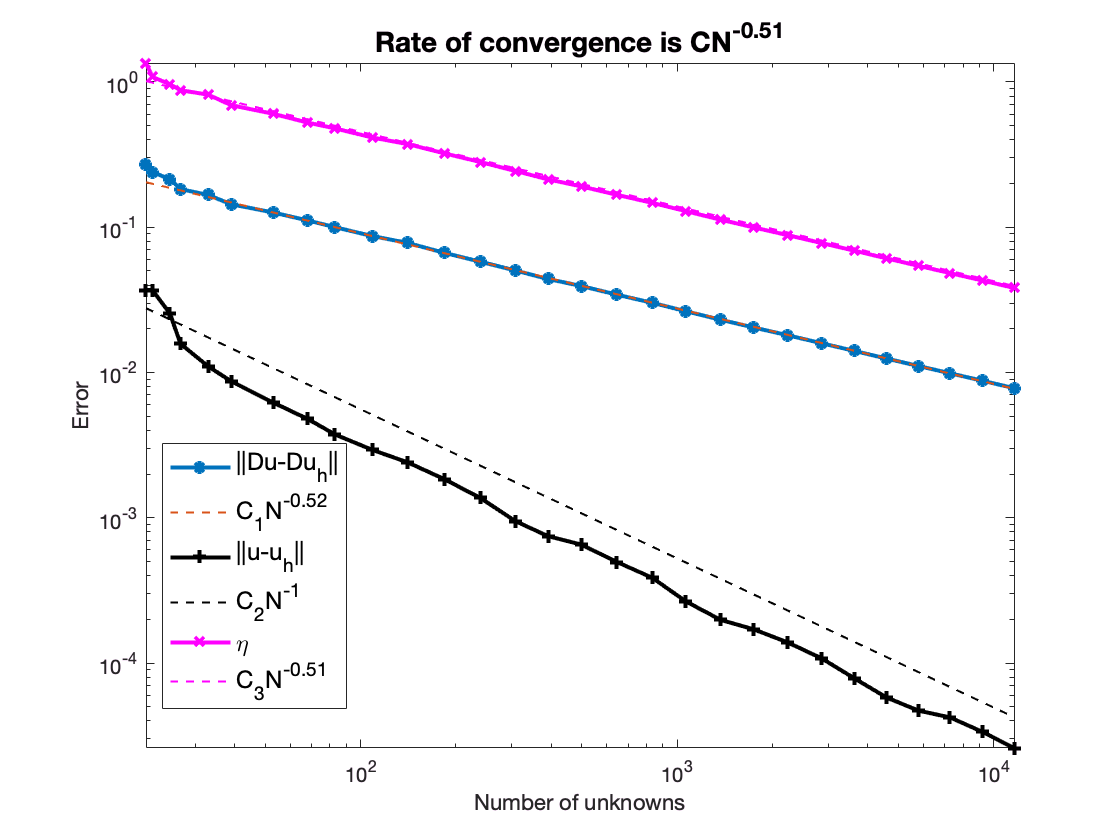

figure;
showrate3(N(1:k),errH1(1:k),10,'-*','||Du-Du_h||',...
          N(1:k),errL2(1:k),10,'k-+','||u-u_h||',...
          N(1:k),erreta(1:k),10,'m-x','\eta');

The solution has a sharp gradient near the origin and the adaptive FEM automatically refines the mesh near the singularity. Optimal rate of convergence in terms of number of unknowns, i.e., 

                                            
$$\|\nabla (u - u_h) \|\leq C N^{-0.5}$$
 

is observed. For quasi-uniform meshes in 2D, $N^{-0.5} \approx h$ is first order. The a posteriori error estimator $\eta$ is an upper bound of the error and also decay in an optimal order. The L2-norm of the error converges in optimal order too, i.e., $\| u - u_h \| \leq C N^{-1}$.